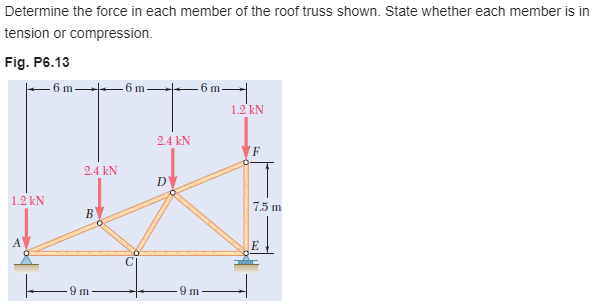

# member data

u = symunit;
E = sym('E');
A = sym('A');
thetaAB = atand(sym(7.5/18))*u.deg;
thetaBD = thetaAB;
thetaDF = thetaAB;
jointB = [6 6*7.5/18]*u.m;
jointD = [12 12*7.5/18]*u.m;
jointF = [18 7.5]*u.m;
thetaBC = atand(jointB(2)/(3*u.m))*u.deg;
thetaCD = atand(jointD(2)/(3*u.m))*u.deg;
thetaDE = atand(jointD(2)/(6*u.m))*u.deg;

# truss

t = Truss;
t = t.add('load', 'reaction', {'Rax' 'Ray'}, [0 0]);
t = t.add('load', 'reaction', {0 'Rey'}, [18 0]*u.m);
t = t.add('load', 'applied', [0 -1.2]*u.kN, [0 0]);
t = t.add('load', 'applied', [0 -2.4]*u.kN, jointB);
t = t.add('load', 'applied', [0 -2.4]*u.kN, jointD);
t = t.add('load', 'applied', [0 -1.2]*u.kN, jointF);
t = t.add('joint', 'A', [0 0]);
t = t.add('joint', 'B', jointB);
t = t.add('joint', 'C', [9 0]*u.m);
t = t.add('joint', 'D', jointD);
t = t.add('joint', 'E', [18 0]*u.m);
t = t.add('joint', 'F', jointF);
t = t.add('member', 'Fab', [0 0], jointB);
t = t.add('member', 'Fac', [0 0], [9 0]*u.m);
t = t.add('member', 'Fbc', jointB, [9 0]*u.m);
t = t.add('member', 'Fbd', jointB, jointD);
t = t.add('member', 'Fcd', [9 0]*u.m, jointD);
t = t.add('member', 'Fce', [9 0]*u.m, [18 0]*u.m);
t = t.add('member', 'Fde', jointD, [18 0]*u.m);
t = t.add('member', 'Fdf', jointD, jointF);
t = t.add('member', 'Fef', [18 0]*u.m, jointF);

# solution

[us fs rs ua fa ra] = t.solve('factor'); %#ok
ua_vpa = vpa(ua, 5) %#ok

$$ua\_vpa = \left(\begin{array}{cc} u_{1} & 0\\ v_{1} & 0\\ u_{2} & \frac{48.109}{A\,\text{E}}\,\mathrm{kN}\,m\\ v_{2} & -\frac{220.92}{A\,\text{E}}\,\mathrm{kN}\,m\\ u_{3} & \frac{51.84}{A\,\text{E}}\,\mathrm{kN}\,m\\ v_{3} & -\frac{201.2}{A\,\text{E}}\,\mathrm{kN}\,m\\ u_{4} & -\frac{10.198}{A\,\text{E}}\,\mathrm{kN}\,m\\ v_{4} & -\frac{151.29}{A\,\text{E}}\,\mathrm{kN}\,m\\ u_{5} & \frac{77.76}{A\,\text{E}}\,\mathrm{kN}\,m\\ v_{5} & 0\\ u_{6} & -\frac{69.483}{A\,\text{E}}\,\mathrm{kN}\,m\\ v_{6} & -\frac{9.0}{A\,\text{E}}\,\mathrm{kN}\,m \end{array}\right)$$

fa_vpa = vpa(fa, 3) %#ok

$$fa\_vpa = \left(\begin{array}{cc} \mathrm{Fab} & -6.24\,\mathrm{kN}\\ \mathrm{Fac} & 5.76\,\mathrm{kN}\\ \mathrm{Fbc} & -2.5\,\mathrm{kN}\\ \mathrm{Fbd} & -4.16\,\mathrm{kN}\\ \mathrm{Fcd} & 1.87\,\mathrm{kN}\\ \mathrm{Fce} & 2.88\,\mathrm{kN}\\ \mathrm{Fde} & -3.75\,\mathrm{kN}\\ \mathrm{Fdf} & 0\\ \mathrm{Fef} & -1.2\,\mathrm{kN} \end{array}\right)$$

ra_vpa = vpa(ra) %#ok

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Rax} & 0\\ \mathrm{Ray} & 3.6\,\mathrm{kN}\\ \mathrm{Rey} & 3.6\,\mathrm{kN} \end{array}\right)$$

clear ua_vpa fa_vpa ra_vpa;